# Two-tanks example (level set method)

The purpose of this example is to illustrate the usage of the level set method and is taken from [1].

The scripts developed in this example can be opened by entering

open('example_two_tanks.m')
open('two_tanks.m')

in the command window.

Two tanks must be filled with water by controlling the throttle valve opening ($u_1$), which controls the total water intake, and the direction valve opening ($u_2$), which controls how the intake flow is split between them. The system states $x_1$ and $x_2$ characterize the amount of water contained in each tank.

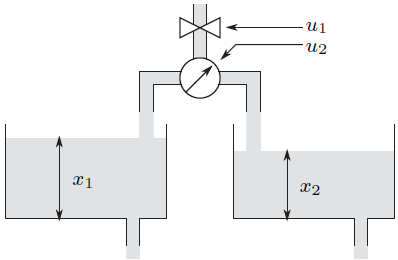

Each tank has a leakage that is proportional to the amount of water it contains; therefore, the system dynamics are


$$\begin{cases}
\dot{x}_1 = - \frac{1}{2} x_1(t) + u_1(t) u_2(t), \\
\dot{x}_2 = -\frac{1}{2} x_2(t) + u_1(t) (1-u_2(t)).
\end{cases}
$$


The goal is to fill the both tanks from empty ($x(t_0) = [0, 0]^T$) to $x(t_f) = [0.5, 0.5]^T$ while minimizing the total water intake. Additionally, a penalty is set on the control effort of the directional valve $u_2$. The cost functional is:


$$\int_{t_0}^{t_f} u_1(t) + 0.1 |u_2(t) - 0.5| \ \mathrm{d}t,$$


where $t_0 = 0 $ $\text{s}$ and $t_f = 2$ $\text{s}$. The state variables and control efforts are all constrained to be in $ [0, 1]$.

[1] *P. Elbert, S. Ebbesen, and L. Guzzella, “Implementation of Dynamic Programming for n-Dimensional Optimal Control Problems With Final State Constraints, IEEETransactions on Control Systems Technology, vol. 21, no. 3, pp. 924-931, May 2013, doi: 10.1109/TCST.2012.2190935.*

## Solving without the level set option

Load the example by typing

open('example_two_tanks.m')

in the Command Window.

This script contains all the relevant information needed to define the optimization problem we just defined. See also [how to set up a basic problem](matlab:open('./set_up_a_basic_problem.mlx')).

% State variables grids
SVnames = {'Tank #1 level', 'Tank #2 level'};
x1_grid = 0:0.02:1;
x2_grid = 0:0.02:1;
x_grid = {x1_grid, x2_grid};
% Initial state 
x1_init = 0;
x2_init = 0;
x_init = {x1_init, x2_init};
% Final state constraints
x1_final = [0.5 1];
x2_final = [0.5 1];
x_final = {x1_final, x2_final};
% Control variables grids
CVnames = {'Throttle position', 'Direction valve position'};
u1_grid = 0:0.05:1;
u2_grid = 0:0.05:1;
u_grid = {u1_grid, u2_grid};
% Number of stages (time intervals)
Nint = 200;
time = 0:0.01:2;

Create the problem structure object by passing all relevant information to the `DynaProg` function. 

% Create DynaProg object
prob = DynaProg(x_grid, x_init, x_final, u_grid, Nint, @two_tanks);

Let us now attempt to solve the problem without enabling any further option.

% Solve the problem
prob = run(prob);

DP backward progress:100 %
DP forward progress:100 %


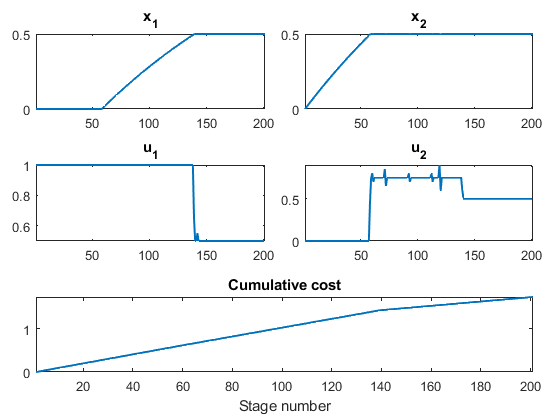

% Plot results
prob.plot;

For this problem and with these settings, the dynamic programming algorithm struggles to achieve the optimal solution and the control trajectories look unstable, whereas the true optimal solution (which can be obtained analitically for this problem) is known not to be.

## Solving with the level set method

Let us now enable the level set method by setting the [`UseLevelSet`](matlab:open('./syntax.mlx')) property to `true`:

% Enable the level set method
prob.UseLevelSet = true;

Equivalently, we could have specified the `'UseLevelSet'` option to true when constructing the problem structure:

prob = DynaProg(x_grid, x_init, x_final, u_grid, Nint, @two_tanks, 'UselevelSet', true);

Now solve the problem again and visualize results:

% Solve the problem
prob = run(prob);

DP backward progress:100 %
DP forward progress:100 %


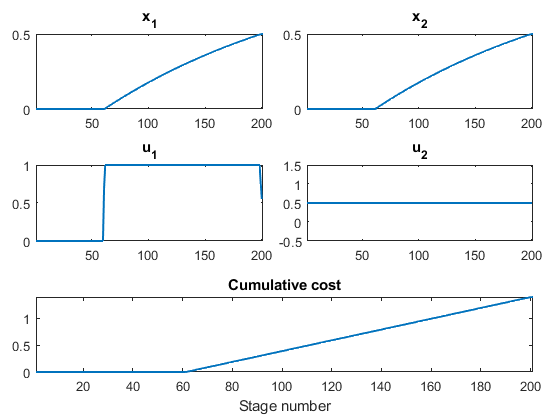

% Plot results
figure
prob.plot;

Enabling the level set greatly improved the solution which is now almost equal to the anaylitical solution, given the same discretizations of the state and control grids.

## Influence of the terminal cost

There are some aspects that may impact the effectivness of the level set method. Amongst them, the definition terminal cost is critical. For example, let us set the terminal cost to a very large number for those values of the terminal state that violate our constraints by setting VFPenalty to `'rift'`.

% Change the terminal cost
prob.VFPenalty = 'rift';
% Solve the problem
prob = run(prob);

DP backward progress:100 %
DP forward progress:100 %


% Plot results
figure
prob.plot;

This setting effectively renders the level set method ineffective. Now let us revert back a linear terminal cost, i.e. let us set the terminal cost to a penalty that is linearly proportional to the distance of the terminal state to the target terminal states, and let us set the proportionality factor for both states to 10. We can do this by using the VFPenalty and VFPenFactors properties.

% Change the terminal cost
prob.VFPenalty = 'linear';
prob.VFPenFactors = [10 10];
% Solve the problem
prob = run(prob);

DP backward progress:100 %
DP forward progress:100 %


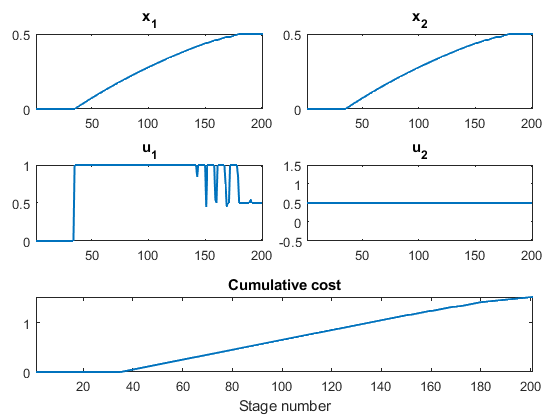

% Plot results
figure
prob.plot;

This time, the level set method did improve our solution to some extent, but the control trajectory for $u_1$ does not look very pretty.

Let us try to reduce the proportionality factors to reduce the impact of the terminal cost on the solution.

% Change the terminal cost
prob.VFPenalty = 'linear';
prob.VFPenFactors = [1 1];
% Solve the problem
prob = run(prob);

DP backward progress:100 %
DP forward progress:100 %


% Plot results
figure
prob.plot;

Finally, we get the proper solution. Thses settings are actually the settings that we got by default when we first solved the problem with the level set method.

When you enable the level set method, and you do not specify a terminal cost, DynaProg sets by default VFPenalty to `'linear' `and sets the VFPenFactors for each state variable to the difference between the upper and lower bound of the corresponding state grid (i.e. $|x_\mathrm{ub} - x_\mathrm{lb}| $).

If these settings do not work for your problem, try to change VFPenFactors`.`